# Owen Rogg Solar Billing Plans Project

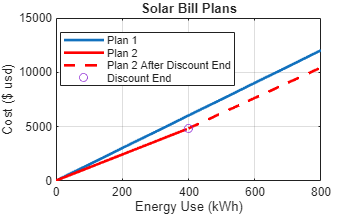


%Made by Owen Rogg, 25 March 2026
%Module 1 project bank, first project;
%community solar billing simulator
clear
clc
close all 
%Setting up each plan, and the energy use on the x-axis.
%Set up x as a colum vector so don't have to make another vector
%for the table, can just use the same one for equations and
%the table of values.
x=(0:5:800)';
y1 = 15 * x +25;
y2 = 12 * x +40;
y3 = 14 * x +(40- 2*400);
% y2 and y3 are the same plan, but there is a discount that
% ends at 400 kWh. Lines beneath this comment stop y2 from
%being displayed past the discount end, and y3 being displayed
%before the discount is over.

y2(x >= 400) = NaN;
y3(x<400) = NaN;
plot(x,y1,"LineWidth",2)
title('Solar Bill Plans')
xlabel('Energy Use (kWh)')
ylabel('Cost ($ usd)')
hold on
plot(x,y2,"LineWidth",2,color="r")
plot(x,y3,"LineWidth",2, "LineStyle","--",Color="r")
plot(400,4820,"o")
grid on
legend("Plan 1","Plan 2","Plan 2 After Discount End","Discount End", "Location","best")

%plotting each of the plans, plan 2 included twice on legend due to
%it technically being 2 seperate lines

% create table of plans
PlanTable = table(x,y1,y2,y3, ... 
    'VariableNames', {'Usage in kWh','Plan 1($)','Plan 2($)', 'Plan 2 After Discount($)'});
disp('Community Solar Bills')

Community Solar Bills


disp(PlanTable)

    Usage in kWh    Plan 1($)    Plan 2($)    Plan 2 After Discount($)
    ____________    _________    _________    ________________________

          0              25          40                  NaN          
          5             100         100                  NaN          
         10             175         160                  NaN          
         15             250         220                  NaN          
         20             325         280                  NaN          
         25             400         340                  NaN          
         30             475         400                  NaN          
         35             550         460                  NaN          
         40             625         520                  NaN          
         45             700         580                  NaN          
         50

%Sum up the total costs of each plan, omit where y2 and y3
% do not exist because they are technically seperate lines
TotalCostPlan1 = sum(y1);
CostPlan2b4 = sum(y2,"omitmissing");
CostPlan2Aft = sum(y3,"omitmissing");
TotalCostPlan2= (CostPlan2b4)+(CostPlan2Aft);
TotalCostPlan1

TotalCostPlan1 = 970025

TotalCostPlan2

TotalCostPlan2 = 811640

% Plan 2 has the least amount of cost, even with the change in
% pricing after the discount. The community should always pick plan 2.
% Plan 1 is only cheaper during the 1st 5kWh. Everything after
% 5kWh leaves plan 2 as the cheaper option.
